# Experiment 3: AM De-Modulation

By Yusuf Ahmed Khan, Serial Number: 12

U= 0.5; %% Modulation index
t = linspace(0, 0.2, 100000); % Time Pereiod of Simulation

**Message Signal**

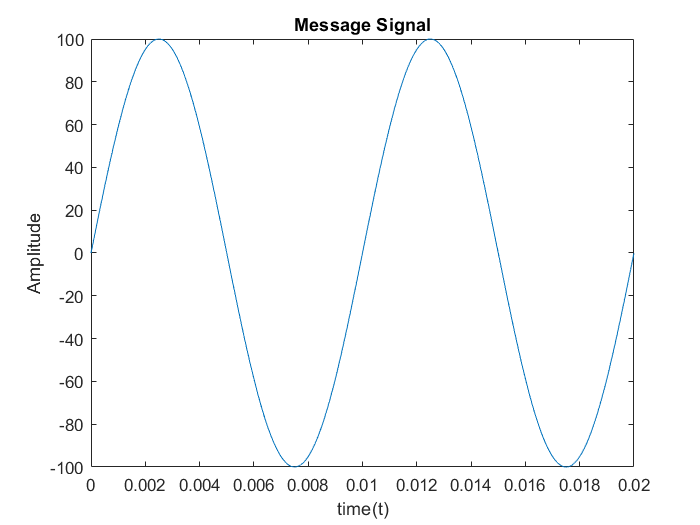

Am = 100; % Message Signal 
fm = 100; % Frequency of message
ym = Am*sin(2*pi*fm*t); %message signal
figure;
plot(t(1:10000), ym(1:10000));

title('Message Signal');
xlabel('time(t)');
ylabel('Amplitude');

**Carrier Signal**

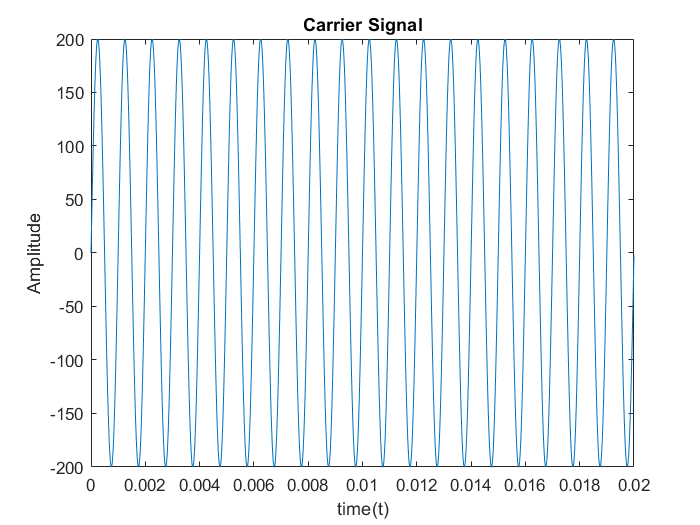

Ac = Am/U; % carrier amplitude
fc = 1000; % carrier frequency
yc = Ac*sin(2*pi*fc*t); %carrier signal

plot(t(1:10000), yc(1:10000));
title('Carrier Signal');
xlabel('time(t)');
ylabel('Amplitude');

**Modulated Signal**

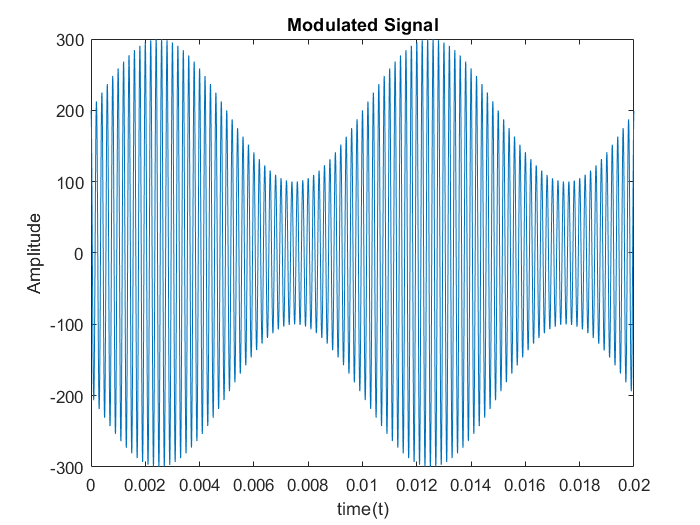

y = ammod(ym, fc, 100000, 0, Ac); % modulated signal

plot(t(1:10000), y(1:10000));
title('Modulated Signal');
xlabel('time(t)');
ylabel('Amplitude');

**Demodulated Signal **

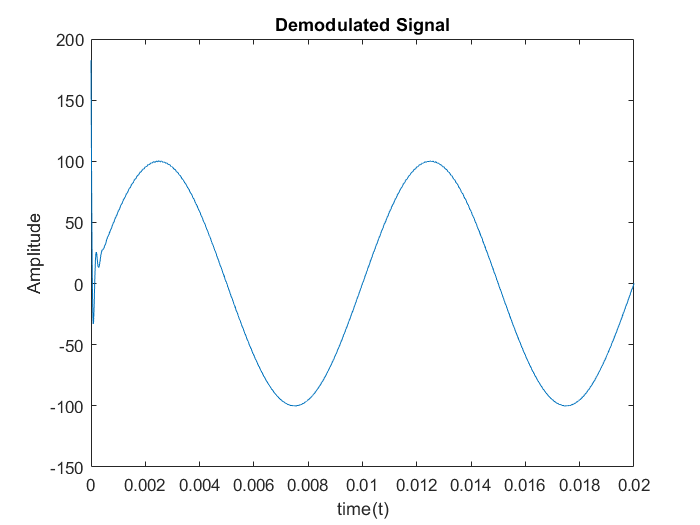

z = amdemod(y, fc, 100000, 0, Ac); % demodulated signal

plot(t(1:10000), z(1:10000));
title('Demodulated Signal');
xlabel('time(t)');
ylabel('Amplitude');

%ylim([-10, 10]);

**Plotting it all together**

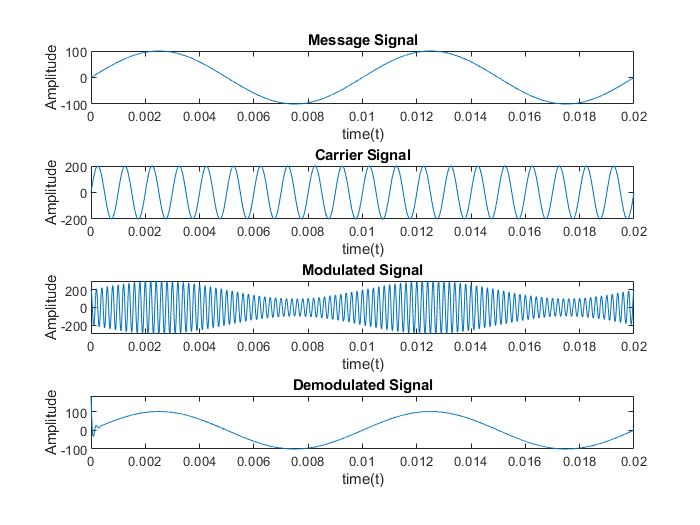

subplot(4, 1, 1);
plot(t(1:10000), ym(1:10000));
title('Message Signal');
xlabel('time(t)');
ylabel('Amplitude');
subplot(4, 1, 2);
plot(t(1:10000), yc(1:10000));
title('Carrier Signal');
xlabel('time(t)');
ylabel('Amplitude');
subplot(4, 1, 3);
plot(t(1:10000), y(1:10000));
title('Modulated Signal');
xlabel('time(t)');
ylabel('Amplitude');
subplot(4, 1, 4);
plot(t(1:10000), z(1:10000));
title('Demodulated Signal');
xlabel('time(t)');
ylabel('Amplitude');

***Thank You***

***By Yusuf Ahmed Khan***